# Compensator Design Tools - INEL 5508

This script helps perform calculations, in turn saving a lot of time.

% Desired performance characteristics
clear all;
close all;
clc;


% %O.S. <= 15%
percent_overshoot = 15; % [%]

% T_s <= 6 seg
settling_time = 3.5; % [seg]

% Sampling Time
T = 0.05; % [seg]

% Choose zeta and omega_n
zeta_max = abs(log(percent_overshoot / 100)) / sqrt((log(percent_overshoot / 100))^2 + pi^2)

zeta_max = 0.5169

zeta = 0.6 %

zeta = 0.6000

omega_n_min = 4 / (zeta * settling_time)

omega_n_min = 1.9048

omega_n = 1.5 % [rad/s]

omega_n = 1.5000


% Find second-order system reponse poles
omega_d = omega_n * sqrt(1 - zeta^2); % [rad/s]
continuous_desired_poles = [-zeta * omega_n + 1j*omega_d; -zeta * omega_n - 1j*omega_d]

continuous_desired_poles =   -0.9000 + 1.2000i
  -0.9000 - 1.2000i


discrete_desired_poles = exp(continuous_desired_poles * T)

discrete_desired_poles =    0.9543 + 0.0573i
   0.9543 - 0.0573i



% Prepare the plant transfer function
G_p = zpk([-3.5954, -0.258], [1, 0.9048, 0.9512], 0.04014E-3, T);
G_p.Name = 'G_m';
G_p.InputName = 'V_m';
G_p.InputUnit = 'V';
G_p.OutputName = 'theta_m';
G_p.OutputUnit = 'rad';
G_p

G_p =
 
  From input "V_m" to output "theta_m":
  4.014e-05 (z+3.595) (z+0.258)
  -----------------------------
   (z-1) (z-0.9512) (z-0.9048)
 
Name: G_m
Sample time: 0.05 seconds
Discrete-time zero/pole/gain model.



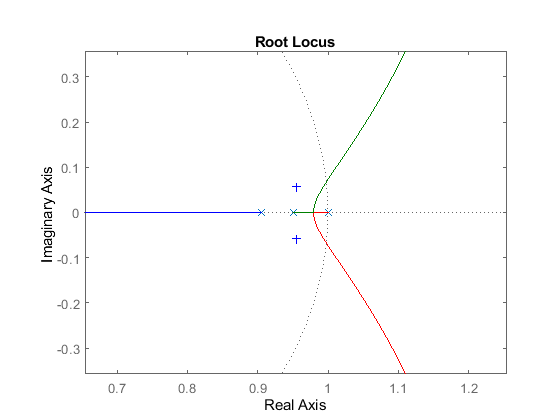


% Plot the root locus for the open-loop plant and the desired pole location
hold on;
rlocus(G_p);
scatter(real(discrete_desired_poles'), imag(discrete_desired_poles'), 'b+');
rl_zoom = 0.3;
xlim([real(discrete_desired_poles(1)) - rl_zoom, real(discrete_desired_poles(1)) + rl_zoom]);
ylim([-abs(imag(discrete_desired_poles(1))) - rl_zoom, abs(imag(discrete_desired_poles(1))) + rl_zoom]);
hold off;

## Phase Lead Compensator

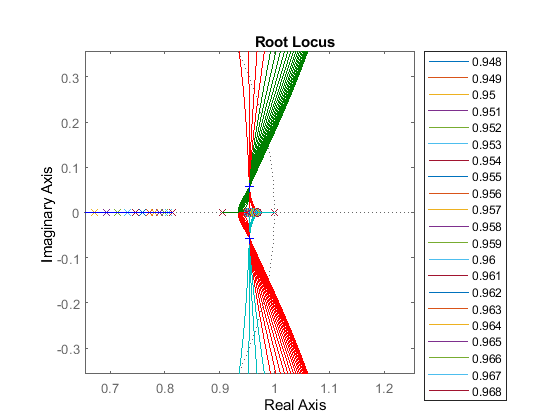

lead_compensator_zeroes = linspace(0.948, 0.968, 21);

% Angular condition:
angle_condition = 0; % rad
for z_0 = zero(G_p)'
    angle_condition = angle_condition + angle(discrete_desired_poles(1) - z_0);    
end
for z_p = pole(G_p)'
    angle_condition = angle_condition - angle(discrete_desired_poles(1) - z_p);
end

% Convert to angle between -pi and pi [rad]
angle_condition = mod(abs(angle_condition), pi);

functions_to_plot = [];
for lead_copmensator_zero = lead_compensator_zeroes
    % Calculate the lead compensator zero's theta and desired pole theta
    theta_zero = angle(discrete_desired_poles(1) - lead_copmensator_zero);
    theta_pole = theta_zero - angle_condition;
    
    % Show warning if zero is problematic
    if theta_pole < 0
        warning("theta_pole is less than 0 for zero in " + num2str(lead_copmensator_zero) + ", where the theta_zero is " + num2str(rad2deg(theta_zero)));
        continue;
    end
    
    % Calculate the lead compensator's pole location
    lead_compensator_pole = real(discrete_desired_poles(1)) - imag(discrete_desired_poles(1)) / tan(theta_pole);
    
    % Magnitude Condition
    lead_compensator_K = abs(discrete_desired_poles(1) - lead_compensator_pole) / abs(discrete_desired_poles(1) - lead_copmensator_zero);
    lead_compensator_K = lead_compensator_K / abs(evalfr(G_p, discrete_desired_poles(1)));
    
    % Lead compensator
    G_lead = zpk(lead_copmensator_zero, lead_compensator_pole, lead_compensator_K, T);
    
    % Plot function only if system is table
    if max(abs(zero(G_lead * G_p + 1))) <= 1 && sum(abs(zero(G_lead * G_p + 1)) == 1) <= 1
        functions_to_plot = [functions_to_plot; {num2str(lead_copmensator_zero), G_lead}];
    end    
end

% Plot root loci
figure('Name', 'Root Loci');
hold on;
for compensated_plant = functions_to_plot(:,2)'
    rlocus(compensated_plant{1} * G_p);
end
scatter(real(discrete_desired_poles'), imag(discrete_desired_poles'), 'b+');
xlim([real(discrete_desired_poles(1)) - rl_zoom, real(discrete_desired_poles(1)) + rl_zoom]);
ylim([-abs(imag(discrete_desired_poles(1))) - rl_zoom, abs(imag(discrete_desired_poles(1))) + rl_zoom]);
hold off;
legend(functions_to_plot(:,1)', 'Location', "bestoutside");

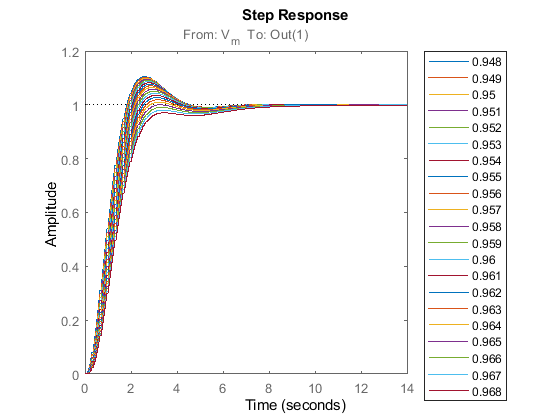


% Plot the closed-loop step response
figure('Name', 'Step Responses');
hold on;
for compensated_plant = functions_to_plot(:,2)'
    step(feedback(compensated_plant{1} * G_p, 1));
end
hold off;
legend(functions_to_plot(:,1)', 'Location', "bestoutside");

## Phase Lag Compensator

% We will reuse functions_to_plot
clear functions_to_plot

% Update the plant with the lead compensator you want to use
G_p = zpk([0.948], [-0.3724], 33.115, T) * zpk([-3.5954, -0.258], [1, 0.9048, 0.9512], 0.04014E-3, T);

% Determine K_d, which indicates how many times you want to reduce e_ss
n = 10

n = 10

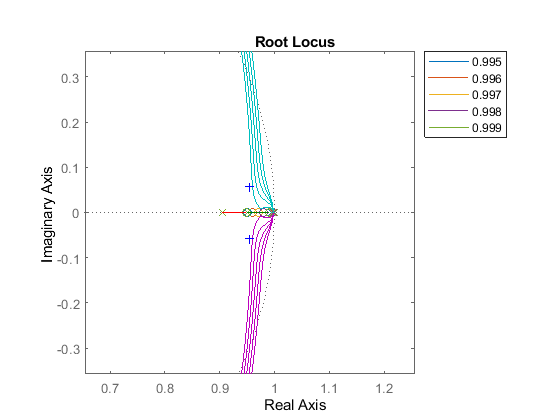

K_u = 33.115; % Taken directly from the lead compensator
K_d = 1/n;
K_c = K_u / K_d;

% Select a lag compensator pole, which must be close to z=1
lag_compensator_poles = 0.99:0.001:0.999;

% Calculate the lag compensator's zero
lag_compensator_zeroes = 1 - (1 - lag_compensator_poles) ./ K_d;

functions_to_plot = [];
for idx = 1:length(lag_compensator_poles)
    % Skip cases where z_0 > z_p
    if lag_compensator_poles(idx) < lag_compensator_zeroes(idx)
        warning("For z_p = " + num2str(lag_compensator_poles(idx)) + ", the compensator is not a lag one");
        continue;
    end
    
    % Lag Compensator
    G_lag = zpk(lag_compensator_zeroes(idx), lag_compensator_poles(idx), n, T);
    
    % Plot function only if system is table
    if max(abs(zero(G_lag * G_p + 1))) <= 1 && sum(abs(zero(G_lag * G_p + 1)) == 1) <= 1
        functions_to_plot = [functions_to_plot; {num2str(lag_compensator_poles(idx)), G_lag}];
    end  
end

% Plot root loci
figure('Name', 'Root Loci');
hold on;
for compensated_plant = functions_to_plot(:,2)'
    rlocus(compensated_plant{1} * G_p);
end
scatter(real(discrete_desired_poles'), imag(discrete_desired_poles'), 'b+');
xlim([real(discrete_desired_poles(1)) - rl_zoom, real(discrete_desired_poles(1)) + rl_zoom]);
ylim([-abs(imag(discrete_desired_poles(1))) - rl_zoom, abs(imag(discrete_desired_poles(1))) + rl_zoom]);
hold off;
legend(functions_to_plot(:,1)', 'Location', "bestoutside");

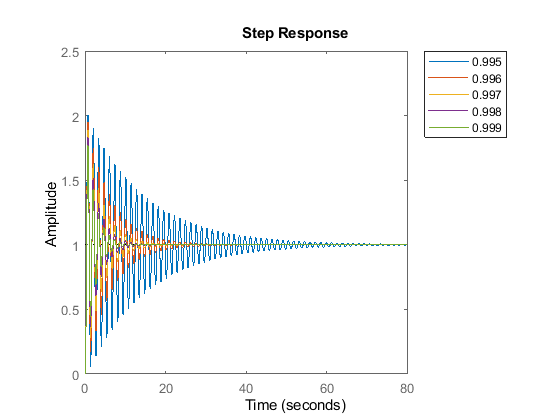


% Plot the closed-loop step response
figure('Name', 'Step Responses');
hold on;
for compensated_plant = functions_to_plot(:,2)'
    step(feedback(compensated_plant{1} * G_p, 1));
end
hold off;
legend(functions_to_plot(:,1)', 'Location', "bestoutside");

G_lead = zpk([0.948], [-0.3724], 33.115, T);
